# Support Vector Machines

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

Use the whole dataset (without splitting) to train a standard Support Vector Machine (SVM) and visualise its linear decision boundary. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset using default hyperparameters [2 marks]

- Generating a "grid" of testing data which spans the minimum and maximum value of each feature in the training dataset [8 marks]

- Using your trained SVM to classifiy the testing data you have generated [2 marks]

- Generating a scatter plot of your training data, with each point colour-coded by the associated classification result [2 marks]

- Superimposing the original training data so that it is clearly visible [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

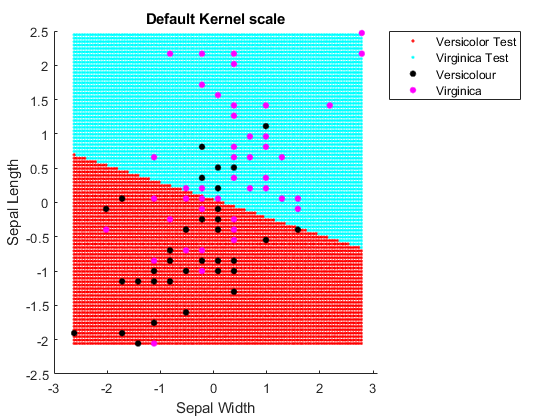

% train an SVM classifier using default hyperparamaters:
m = fitcsvm(examples, labels);

% find the min and the max of both columns in example data:
min1 = min(examples{:,1});
max1 = max(examples{:,1});
min2 = min(examples{:,2});
max2 = max(examples{:,2});


% create an array to hold the grid of visualisation points:
generatedExamples = [];

% create nested for loop to loop from the min and the max of each column:
for i=min1:0.05:max1
    for j=min2:0.05:max2
        % add each value in the grid to the matrix:
        generatedExamples = [generatedExamples; [i j]];
    end
end

hold on
% predict the outcome of each set of values in the grid:
gridpredictions = predict(m, generatedExamples);
% plot the points and their corresponding predictions:
gscatter(generatedExamples(:,1),generatedExamples(:,2),gridpredictions)

% plot the original datapoints to visualize the classifiers accuracy:
gscatter(examples{:,1},examples{:,2},labels,'km')
legend('Versicolor Test', 'Virginica Test', 'Versicolour', 'Virginica', 'Location', "bestoutside");
title("Default Kernel scale")
xlabel("Sepal Width")
ylabel("Sepal Length")

hold off